**Setup**

clc;
clear;
tic
po = [0 0 0]; % point of our plane, here simply the origin
no = [0 1 0]; % normal vector of the plane i.e. pointing along the y-axis
num = 300;
trials = 1;
areas = zeros(num,1,'double');
results = zeros(trials,2,'double');
g = [0 0 0];
beta = 0;

**Create the shape**

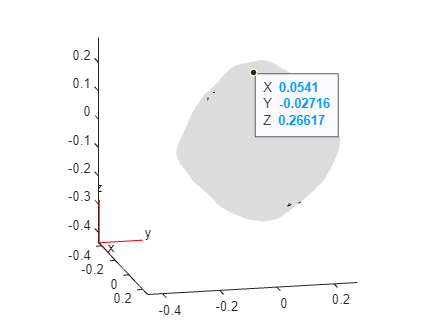

s = importGeometry("Bogus Bennu Shape.stl");
pdegplot(s)

**Get a random uniform sample of *****num***** points on a sphere. **(https://uk.mathworks.com/matlabcentral/fileexchange/37004-suite-of-functions-to-perform-uniform-sampling-of-a-sphere)

for j=1:1:trials
    V=RandSampleSphere(num,'uniform');
    %[V,Tri]=SpiralSampleSphere(num,false);

**Run the pyramid rotation using the previously acquired points on a sphere.**

    for k = 1:length(V)

**Get x-z projection of the shape**

        %get data as a result of rotation
        XX = s.Vertices(:,1);
        YY = s.Vertices(:,2);
        ZZ = s.Vertices(:,3);
        % concat the shape grid
        gr = [XX(:) YY(:) ZZ(:)];
        v = gr - repmat(po,numel(XX(:)),1);
        % dot vector with the normal vector of the plane of intrest
        % this represents the distance from the grid points to our plane along the normal
        d = v(:,1)*no(1) + v(:,2)*no(2) + v(:,3)*no(3); 
        % get the projected points
        projected_grid = gr - d .* repmat(no,numel(XX(:)),1);
        projected_grid = unique(projected_grid,'rows','stable');
        %we need the outer points of the region, acquire this and the area of
        %the region with convex hull.
        [shadow,area] = convhull(projected_grid(:,1),projected_grid(:,3));
        areas(k) = area;
        plot(projected_grid(shadow,1),projected_grid(shadow,3))
        

**Rotate the pyramid**

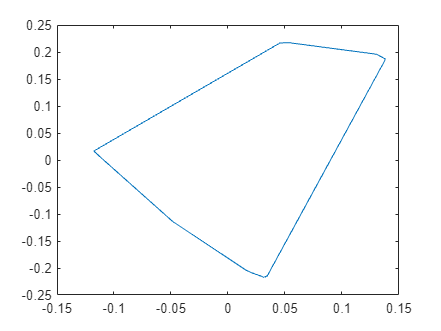

        a = [V(k,1), V(k,2), 0];
        b = [0 0 2];
        if norm(g)==0; g = cross(a,b); continue; end %if the magnitude of the cross product is zero, then continue to the next iteration
        rotate(s,rad2deg(beta),[0 0 0],g);
        g = cross(a,b); %find the cross product between a and b
        beta = acos(V(k,3));        
        rotate(s,-rad2deg(beta),[0 0 0],g);
    end
    results(j,1) = mean(areas);
    results(j,2) = toc;
end

results

results =     0.0931    2.7095
